clear; clc; clf;
% example7.m: comparing efficiency and accuracy of some multistep and
% multistage methods. Problem 1.3.4from text by L.N. Trefethen.
% We are to solve u'(t) = exp( cos(tu(t))), u(0)=0, for t in [0,3]

% Problem specification and 'true' solution
%f = @(t,y) exp(cos(t*y)); u0=0;
f = @(t,y) -10*y + t;
u0 = 1;
%u0 = 0;
t0 = 0;
Tfinal = 3;

odeopts = odeset('RelTol', 1e-10, 'AbsTol', 1e-10, 'Stats', 'on');
% the 'True' solution, computed with a high-accuracy method.
[Ttrue, Ytrue] = ode45(f, [t0, Tfinal], u0, odeopts); u3 = Ytrue(end);

161 successful steps
0 failed attempts
967 function evaluations


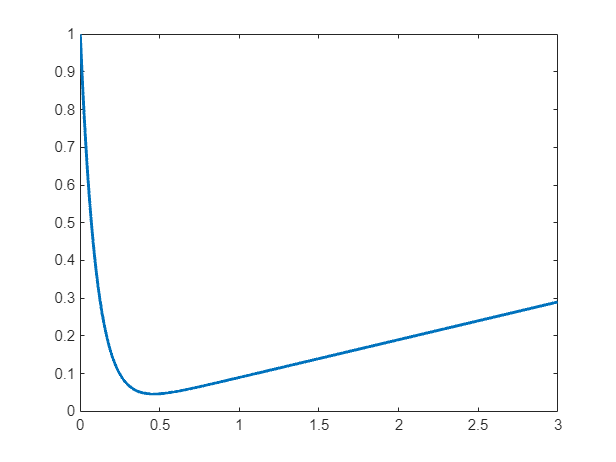

figure();
xlabel('Time t'); ylabel('Y');
plot(Ttrue, Ytrue, 'LineWidth', 2)

% Starting loop over time steps
timestep = 1 ./ (2.^(1:8)); % dt=1/2,1/4,...1/256
M = length(timestep);
FuncEval = zeros(M, 6); %tracking number of function evaluations for each method
ErrorEval = zeros(M, 6); % tracking error

for j = 1:M
    dt = timestep(j);
    t = 0 : dt : Tfinal; 
    N = length(t);

    % FORWARD EULER. 
    % One-step, explicit, first order. Y_{n+1} = Y_{n} + dt f(t_n, Y_{n})
    
    Y_FE = zeros(1, N);
    Y_FE(1) = u0;

    for n = 1:N-1
        Y_FE(n+1) = Y_FE(n) + dt * f(t(n), Y_FE(n));
    end

    % number of function evaluations for forward euler = number of time steps
    FuncEval(j, 1) = N; 
    ErrorEval(j, 1) = norm(Y_FE(N) - u3);
    
    % LEAPFROG RULE. 
    % Multistep, explicit, second order. Y_{n+1} = Y_{n-1} + 2dt [ f(t_n,Y_{n})]
    % Need another starting value, Y_{2}. We take this as a Forward Euler update from y0.
    
    Y_LF = zeros(1, N);
    Y_LF(1) = u0;
    Y_LF(2) = Y_LF(1) + dt * f(t(1), Y_LF(1));

    for n = 2:N-1
        Y_LF(n+1) = Y_LF(n-1) + 2*dt * f(t(n), Y_LF(n));
    end

    % number of function evaluations for Leap Frog = number of time steps
    FuncEval(j, 2) = N; 
    ErrorEval(j, 2) = norm(Y_LF(N) - u3);
    
    % RK4. 
    % Multistage, 4th order.
    Y_RK = zeros(1, N);
    Y_RK(1) = u0;

    for n = 1:N-1
        k1 = dt * f(t(n), Y_RK(n));
        k2 = dt * f(t(n) + dt/2, Y_RK(n) + k1/2);
        k3 = dt * f(t(n) + dt/2, Y_RK(n) + k2/2);
        k4 = dt * f(t(n) + dt, Y_RK(n) + k3);
        Y_RK(n+1) = Y_RK(n) + (k1 + 2*k2 + 2*k3 + k4)/6;
    end

    % number of function evaluations for Leap Frog = number of time steps
    FuncEval(j, 3) = 4*N; 
    ErrorEval(j, 3) = norm(Y_RK(N) - u3);
    
    % ADAMS BASHFORTH (4th order). 
    % Multistep, explicit. 
    % We use the initial iterates of the RK4 method to get starting values.
    
    Y_AB = zeros(1, N);
    Y_AB(1) = u0;
    Y_AB(2:4) = Y_RK(2:4);
    
    for n = 1:N-4
        Y_AB(n+4) = Y_AB(n+3) + (dt/24)*( ...
                    55*f(t(n+3), Y_AB(n+3)) ...
                   -59*f(t(n+2), Y_AB(n+2)) ...
                   +37*f(t(n+1), Y_AB(n+1)) ...
                   -9*f(t(n), Y_AB(n)));
    end

    % 1 new function evaluations for AB4 per time step
    FuncEval(j, 4) = N; 
    ErrorEval(j, 4 ) = norm(Y_AB(N) - u3);

    % TRAPEZOIDAL RULE. 
    % One-step, implicit, second order. Y_{n+1} = Y_{n} + dt/2 [ f(t_n,Y_{n}) + f(t_n+1, Y_{n+1})]
    % Use Matlab's 'fsolve' to solve -z+Y_n+dt/2 [f(t_n,Y_n) + f(t_n+1,z)]=0 for z, given Y_n. Set Y_{n+1}=z.

    Y_Tr = zeros(1, N);
    Y_Tr(1) = u0;
    options = optimset('Display','off');
    
    for n = 1:N-1
        g = @(z) -z + Y_Tr(n) + (dt/2) * f(t(n+1), z) + (dt/2) * f(t(n), Y_Tr(n));
        % solve nonlinear equation for z, initial guess= Y_{n}
        Y_Tr(n+1) = fsolve(g, Y_Tr(n), options);
    end

    % 1 new function evaluations for AB4 per time step
    FuncEval(j, 5) = N;
    ErrorEval(j, 5) = norm(Y_Tr(N) - u3);

    % MATLAB SOLVER
    % maximum step size of dt and changing tolerance

    sodeopts = odeset('MaxStep', dt, 'Stats', 'on');
    sol = ode23(f, [t0,Tfinal], u0, sodeopts);
    sol.stats;
    FuncEval(j, 6) = sol.stats.nfevals; % 1 new function evaluations for AB4 per time step
    ErrorEval(j, 6) = norm(sol.y(end)-u3);
end

26 successful steps
1 failed attempts
82 function evaluations
28 successful steps
0 failed attempts
85 function evaluations
36 successful steps
0 failed attempts
109 function evaluations
55 successful steps
0 failed attempts
166 function evaluations
97 successful steps
0 failed attempts
292 function evaluations
193 successful steps
0 failed attempts
580 function evaluations
384 successful steps
0 failed attempts
1153 function evaluations
768 successful steps
0 failed attempts
2305 function evaluations


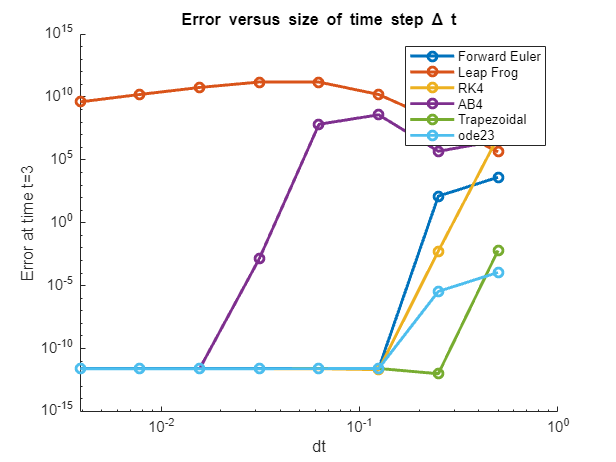

figure;
xlabel('dt'); ylabel('Error at time t=3');
title('Error versus size of time step \Delta t')

hold on;
set(gca, 'XScale', 'log', 'YScale', 'log');
for j = 1:6
    loglog(timestep, ErrorEval(:, j), 'o-', 'LineWidth', 2)
end
legend('Forward Euler', 'Leap Frog', 'RK4', 'AB4', 'Trapezoidal', 'ode23');
hold off;

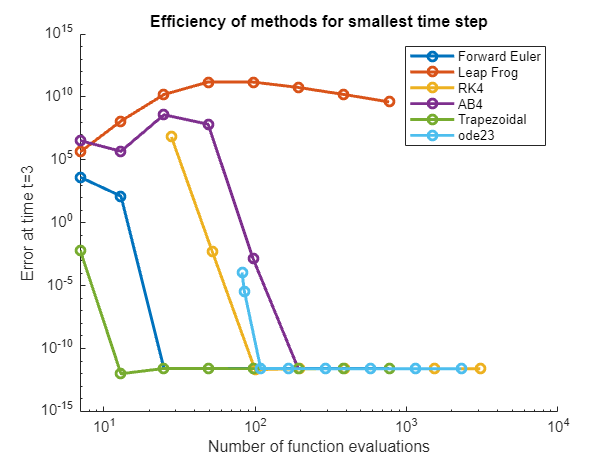

figure;
title('Efficiency of methods for smallest time step')
xlabel('Number of function evaluations'); ylabel('Error at time t=3');

hold on;
set(gca,'XScale', 'log', 'YScale', 'log');
for j = 1:6
    loglog(FuncEval(:, j), ErrorEval(:, j), 'o-', 'LineWidth', 2)
end
legend('Forward Euler', 'Leap Frog', 'RK4', 'AB4','Trapezoidal','ode23');
hold off;